% Clear workspace
clear; clc;

% directory where data is stored
DIR = 'C:\Users\Sohaib Bhatti\OneDrive - The Cooper Union for the Advancement of Science and Art\Senior Spring\Data Driven Methods\SVD\Airfoil Analysis';

paramsFile = fullfile(DIR,'airfoilDNS_parameters.h5');


dt_field = h5read(paramsFile,'/dt_field'); % timestep for field variables (velocity and vorticity)
dt_force = h5read(paramsFile,'/dt_force'); % timestep for scalar quantities
Re = h5read(paramsFile,'/Re');
FreqsAll = h5read(paramsFile,'/frequencies'); % pitching frequencies
alpha_p = h5read(paramsFile,'/alpha_p'); % pitching amplitude (deg)
alpha_0s = h5read(paramsFile,'/alpha_0s'); % base angles of attack (deg) (25 and 30)
pich_axis = h5read(paramsFile,'/pitch_axis'); % 0.5, midchord pitching

%h5disp(paramsFile)

load and plot snapshots for various airfoil kinematics each simulation contains 401 snapshots, with uniform timestep of 0.1 c/U_\infty time units

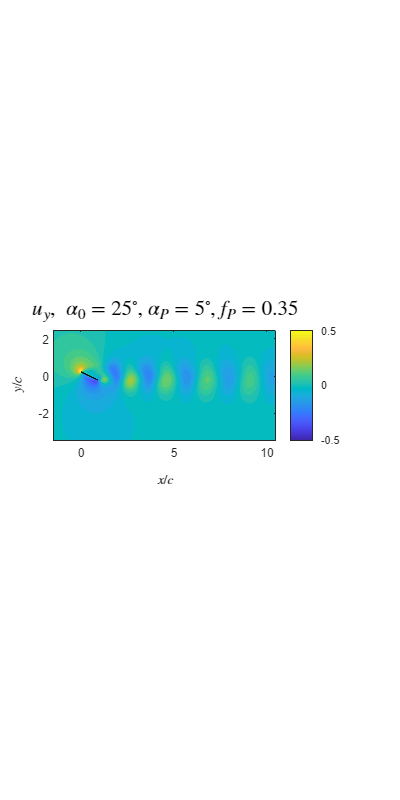

BaseAngle = 25; % options are 25 and 30 deg

Freqs = [0.35]; % choose pitching frequencies to plot
% must be from the set 0.05, 0.1, 0.2, 0.25, 0.3, 0.35, 0.4, 0.5

FreqLabels = {'0p35'}; % for loading files, must match selected Freqs

% load and plot snapshots
tstep = 1; % timestep to plot

% load spatial grid, and time vectors
filenameGrid = fullfile(DIR,'airfoilDNS_grid.h5');

x = h5read(filenameGrid,'/x');
y = h5read(filenameGrid,'/y');
nx = length(x);
ny = length(y);


figure
for ff = 1:length(Freqs)
    Freq = Freqs(ff);
    FreqStr = FreqLabels{ff};
    
    % load velocity field data
    filename = fullfile(DIR,['airfoilDNS_a',num2str(BaseAngle),'f',FreqStr,'.h5']);
    %ux = h5read(filename,'/ux'); % streamwise velocity
    uy = h5read(filename,'/uy'); % transverse velocity
    %vort  = h5read(filename,'/uy'); % vorticity
    
    % load (time-varying) airfoil coordinates
    xa = h5read(filename,'/xa');
    ya = h5read(filename,'/ya');
    t_field = h5read(filename,'/t_field');
    t_force = h5read(filename,'/t_force');
    nt = length(t_field);
    
    subplot(length(Freqs),1,ff)
    [~,hc] = contourf(x,y,squeeze(uy(:,:,tstep)).',linspace(-1.5,1.5,80));
    set(hc,'LineStyle','none');
    caxis([-0.5,0.5]); % plot with same range for each case
    hold on
    % plot airfoil coordinates at appropriate timestep
    plot(xa(:,tstep),ya(:,tstep),'k-')
    
    colorbar;
    axis image;
    axis equal
    title(['$u_y, \ \alpha_0 = ', num2str(BaseAngle),'^\circ$, $\alpha_P = ',...
        num2str(alpha_p) '^\circ$, $f_P = ',num2str(Freq),'$'],...
        'interpreter','latex','fontsize',16)
    
    xlabel('$x/c$','Interpreter','Latex');
    ylabel('$y/c$','Interpreter','Latex');
    set(gcf,'position',[100 100 400 800])
end

## load and plot forces and airfoil kinematics for a single case

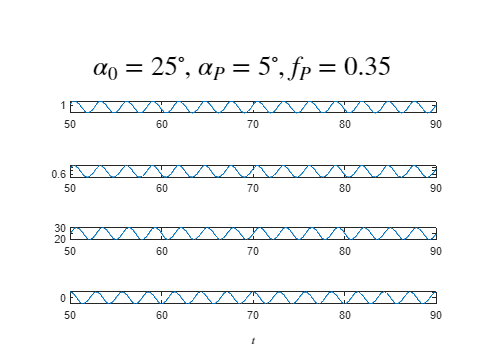

angle = 25;
FreqStr = '0p35';
Freq = 0.35;

filename = fullfile(DIR,['airfoilDNS_a',num2str(angle),'f',FreqStr,'.h5']);

Cl = h5read(filename,'/Cl'); % lift coefficient
Cd = h5read(filename,'/Cd'); % drag coefficient
alpha = h5read(filename,'/alpha'); % angle of attack
alphadot = h5read(filename,'/alphadot'); % angle of attack

figure
subplot(4,1,1)
plot(t_force,Cl)
ylabel('$C_L$','Interpreter','Latex')
subplot(4,1,2)
plot(t_force,Cd)
ylabel('$C_D$','Interpreter','Latex')

subplot(4,1,3)
plot(t_force,alpha)
hold on
%plot(t_force,BaseAngle-AlphaP*sin(2*pi*Freq*t_force),'--') % should match
ylabel('$\alpha$','Interpreter','Latex')

subplot(4,1,4)
plot(t_force,alphadot)
hold on
%plot(t_force,-2*pi*Freq*AlphaP*cos(2*pi*Freq*t_force),'--') % should match
ylabel('$\dot\alpha$','Interpreter','Latex')
xlabel('$t$','Interpreter','Latex')
sgtitle(['$\alpha_0 = ', num2str(BaseAngle),'^\circ$, $\alpha_P = ',...
    num2str(alpha_p) '^\circ$, $f_P = ',num2str(Freq),'$'],'interpreter','latex','fontsize',20)

## Run simple dmd code

% run dmd

meanSub = 1; % subtract mean prior to performing DMD

%filename = fullfile(DIR,['airfoilDNS_a',num2str(BaseAngle),'f',FreqStr,'.h5']);
filename = fullfile(DIR,"airfoilDNS_a25f0p35.h5");
ux = h5read(filename,'/ux'); % streamwise velocity
uy = h5read(filename,'/uy'); % transverse velocity
uxreshape = reshape(ux,nx*ny,nt);
uyreshape = reshape(uy,nx*ny,nt);
data = [uxreshape;uyreshape];

    
if meanSub
    dataMean = mean(data,2);
    data = data-dataMean*ones(1,nt);
end

size(data)

ans =       358202         401


size(dataMean*ones(1,nt))

ans =       358202         401




r= 100; % optional truncation of SVD (set to 0 for no truncation)
[Phi, Lambda,Atilde,Amplitudes] = calc_dmd(data,r);

Unrecognized function or variable 'calc_dmd'.


Eigscts = log(Lambda)/dt_field; % find eignevalues in continuous time

figure
stem(imag(Eigscts)/(2*pi), abs(Amplitudes.*(Lambda))/max(abs(Amplitudes.*(Lambda))),'-','linewidth',2)

xlim([-0.02 1.5])
ylim([0 1.2])

xlabel('Frequency'), ylabel('DMD mode amplitude (scaled)')
% plot leading 4 DMD modes (ranked by amplitude

% contour plot parameters
MM = 0.01';
v = -1:0.1:1;
v(11)=[];

modeInd = 1;
figure
for ii = 1:4
    
    subplot(4,1,ii)
    % for velocity form
    [cv,ch] = contourf(x,y,transpose(reshape(real(Phi(end/2+1:end,modeInd)),nx,ny)),MM*v);
    caxis([-MM MM]);
    set(gca,'fontsize',14)
    title(['$f = ',num2str(abs(imag(Eigscts(modeInd)))/(2*pi)),'$'],'interpreter','latex','fontsize',22)
    
    if abs(imag(Eigscts(modeInd))) > 0
        modeInd = modeInd +1; % skip plotting complex conjugate modes
    end
    modeInd = modeInd +1;
    axis equal
    axis off
    hold on
    plot(xa(:,:),ya(:,:),'k-')  % plot all airfoil locations
    set(gcf,'position',[100 100 300 700])
    
end
sgtitle({'Leading DMD modes', 'Real($u_x$)'},'Fontsize',22,'Interpreter','latex')